## Import Data and Best Model

% load data
clear
clear all
close all
clc
format shorteng
[dsTrain, dsValidation, dsTest, dsCombined] = import_all("temperature_train.csv", "temperature_val.csv", "temperature_test.csv", "temperature_combined.csv");

% load best model
load('temp_DL.mat')

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];

## Training History

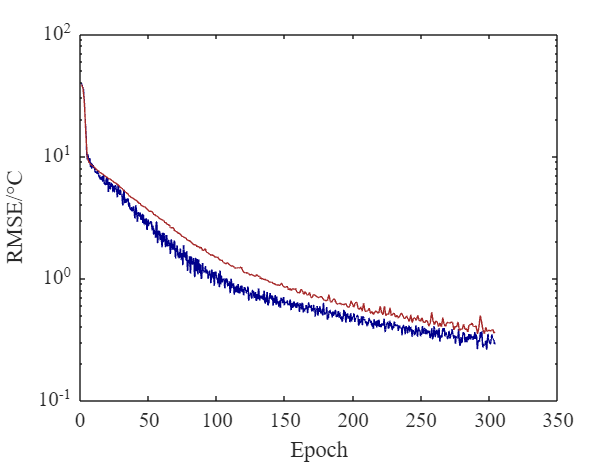

training_RMSE = smoothdata(temp_DL_traininfo.TrainingRMSE, "gaussian", 50);
validation_RMSE = temp_DL_traininfo.ValidationRMSE;
% change minibatch size as needed
MiniBatchSize = 59;
iter = length(training_RMSE);
iter_per_epoch = floor(length(readall(dsTrain)) / MiniBatchSize);
num_epoch = ceil(iter / iter_per_epoch);
epochs = linspace(1,num_epoch,length(training_RMSE));
x = linspace(1,num_epoch,length(training_RMSE));
y = validation_RMSE;
idx = ~any(isnan(y),1);

figure(1)
hold on
plot(epochs, training_RMSE, 'Color', blue)
plot(x(idx),y(idx), 'Color', red)
hold off

v=get(1,'currentaxes');
xlabel("Epoch")
ylabel("RMSE/{{\circ}}C")
% legend("Train (smoothed)", "Validation")
set(v,'FontSize',14,'FontName','Times New Roman', 'YScale','log')
box on

clear iter iter_per_epoch MiniBatchSize idx x y

## Results (Test)

y_test_pred = predict(temp_DL_net,dsTest);
data = readall(dsTest);
y_test = cell2mat(data(:,2));
test_RMSE = rmse(y_test,y_test_pred)

test_RMSE = single
   372.1122e-003


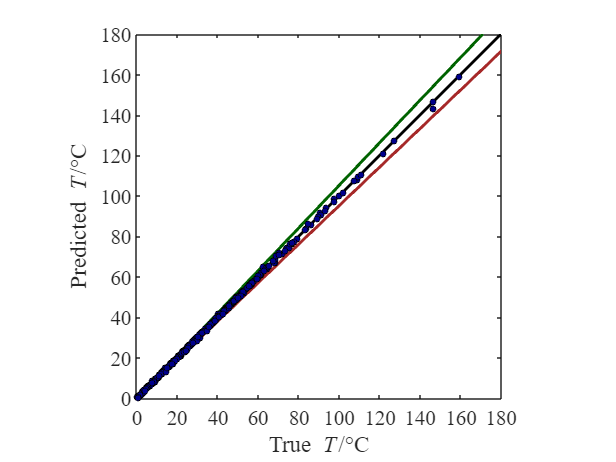

plot_true_pred(2, y_test, y_test_pred, 0, [0 180 0 180])

## Results (All)

y_comb_pred = predict(temp_DL_net,dsCombined);
data = readall(dsCombined);
y_comb = cell2mat(data(:,2));
comb_RMSE = rmse(y_comb,y_comb_pred)

comb_RMSE = single
   313.9846e-003


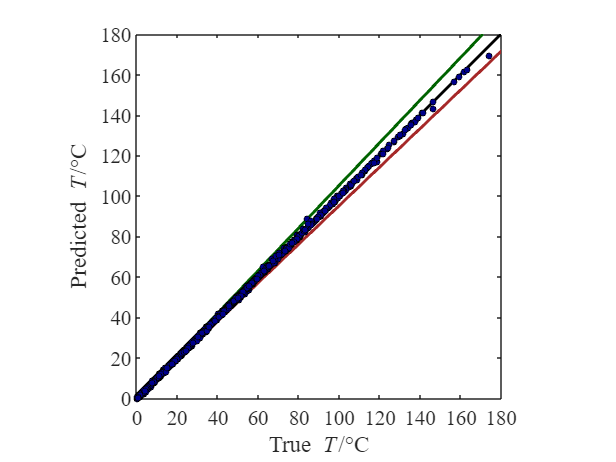

plot_true_pred(2, y_comb, y_comb_pred, 0, [0 180 0 180])

## Others

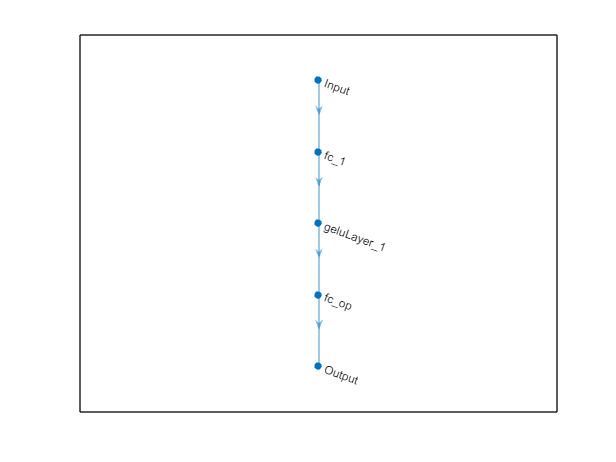

figure(4)
temp_DL_net.plot

temp_DL_net.Layers

ans =   5×1 Layer array with layers:

     1   'Input'         Feature Input       6 features with 'zscore' normalization
     2   'fc_1'          Fully Connected     73 fully connected layer
     3   'geluLayer_1'   GELU                GELU
     4   'fc_op'         Fully Connected     1 fully connected layer
     5   'Output'        Regression Output   mean-squared-error with response 'Response'

temp_DL_net.layerGraph

ans =   LayerGraph with properties:

     InputNames: {'Input'}
    OutputNames: {'Output'}
         Layers: [5×1 nnet.cnn.layer.Layer]
    Connections: [4×2 table]


function plot_true_pred(num, y_true, y_pred, lgnd, axs)
    % set colours
    blue = [0.00 0.00 0.55];
    red = [0.65 0.16 0.16];
    green = [0.00 0.39 0.00];

    figure(num)
    hold on
    % plot points
    s = plot(y_true,y_pred,'o','MarkerEdgeColor','k','MarkerFaceColor',blue,'MarkerSize',4);
    line = [0 axs(2)];
    plot(line, line, "LineWidth", 2, "Color", "k");
    plot(0.95*line, line, "LineWidth", 2, "Color", green);
    plot(1.05*line, line, "LineWidth", 2, "Color", red);
    uistack(s,'top')
    hold off
    
    v=get(num,'currentaxes');
    xlabel("True\rm {\itT}/{{\circ}}C") 
    ylabel("Predicted {\itT}/{{\circ}}C")
    if lgnd == 1
        legend('Ideal','5% Above', '5% Below', '', "FontSize", 18, 'Location', 'nw');
    end
    set(v,'FontSize',14,'FontName','Times New Roman', 'XTick', get(v, 'YTick'), 'XTickLabelRotation', 0);
    axis(axs)
    box on
    axis square
end